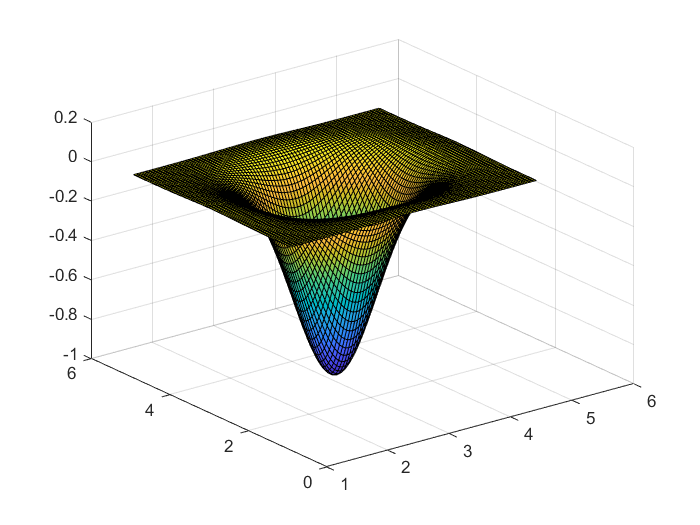

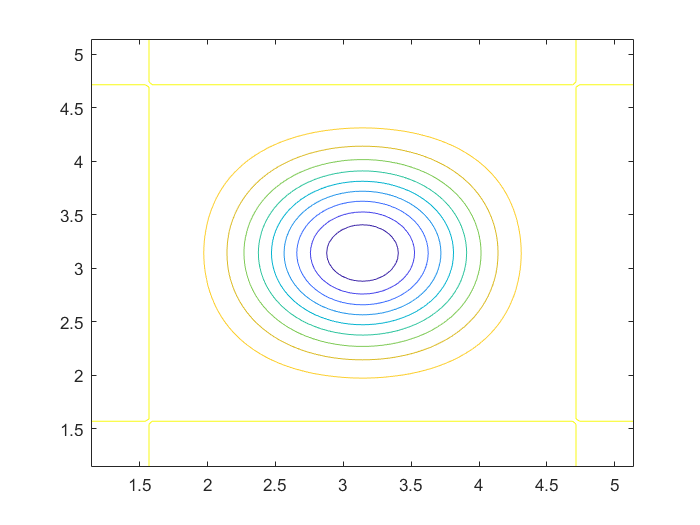

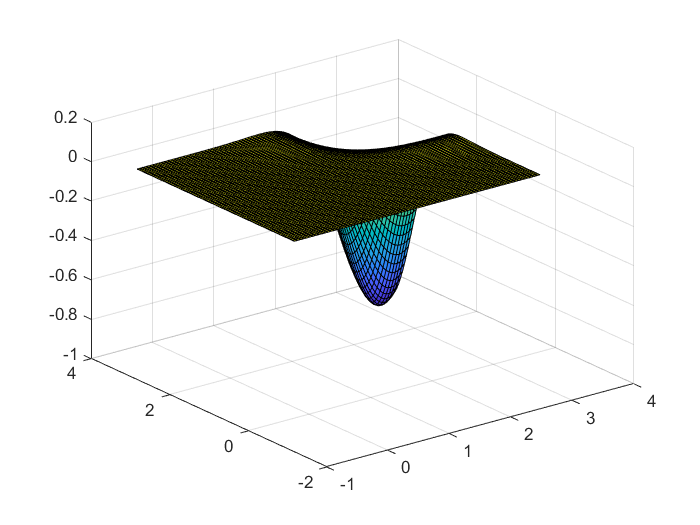

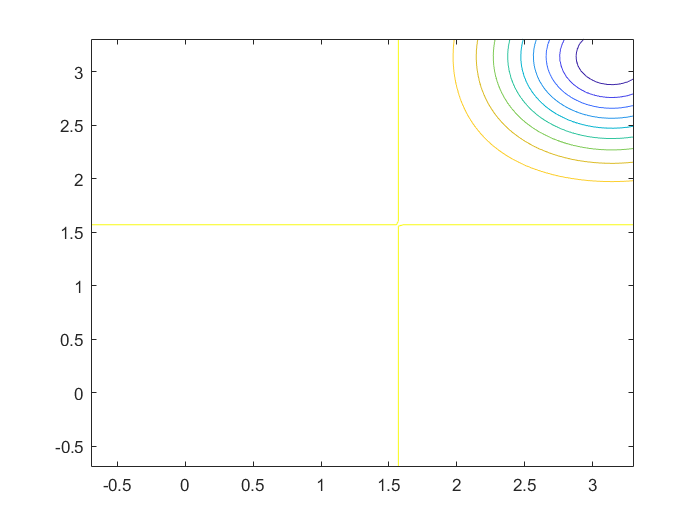

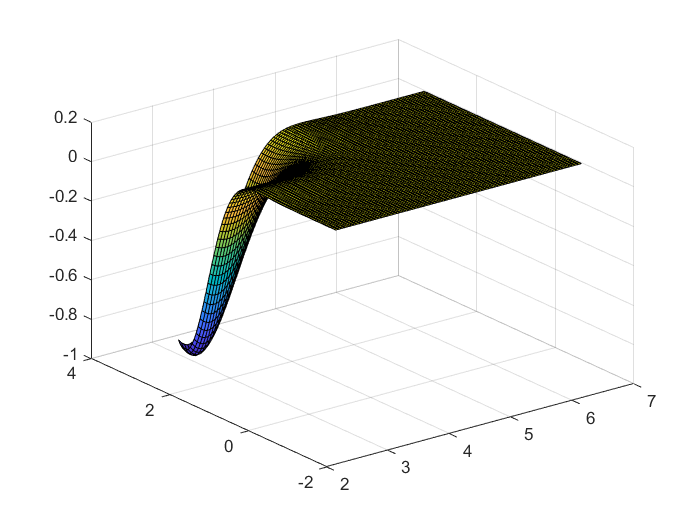

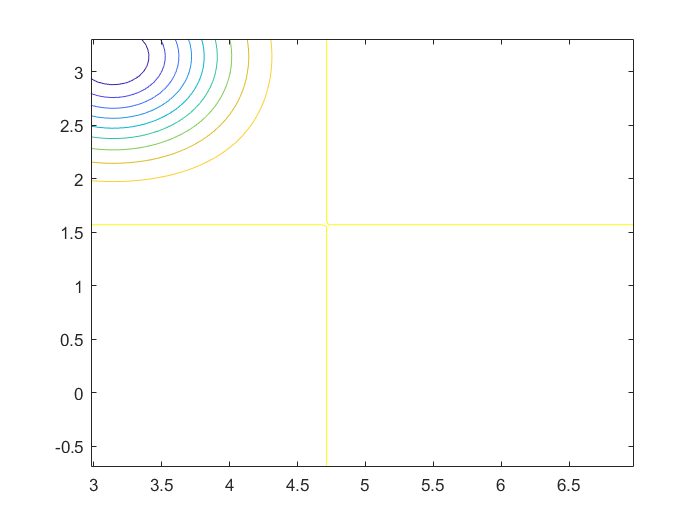

x0 = [0, 1, 4; 0, -1, 1];
for i = 1:3
    f = @(x) -cos(x(1))*cos(x(2))*exp(-(x(1)-pi)^2-(x(2)-pi)^2);
    [xmin2, fmin2] = fminsearch(f, x0(:, i));
    x1 = xmin2(1)-2:0.05:xmin2(1)+2;
    x2 = xmin2(2)-2:0.05:xmin2(2)+2;
    [X, Y] = meshgrid(x1, x2);
    Z = -cos(X).*cos(Y).*exp(-(X - pi).^2 -(Y - pi).^2);
    figure
    surf(X, Y, Z)
    figure
    contour(X, Y, Z)
end

% [xmin2, fmin2] = fminsearch(f, [1, -1]);
% x1 = xmin2(1)-1:0.05:xmin2(1)+1;
% x2 = xmin2(2)-1:0.05:xmin2(2)+1;
% [X, Y] = meshgrid(x1, x2);
% Z = -cos(X).*cos(Y).*exp(-(X - pi)